%% step2_check_result.m
clc; clear; close all;

% 设定分辨率（需与仿真工程保持一致 64x64）
WIDTH  = 64;
HEIGHT = 64;
TOTAL_PIXELS = WIDTH * HEIGHT;

% 1. 读取 Verilog 仿真输出的十六进制文本
sim_file_path = 'C:\Users\jingzifu\Desktop\sim_out.txt';
fid = fopen(sim_file_path, 'r');
if fid == -1
    error('未找到 %s，请确认路径及文件是否存在！', sim_file_path);
end
data_hex = textscan(fid, '%s');
fclose(fid);

hex_lines = data_hex{1};
total_read = length(hex_lines);
fprintf('成功读取 sim_out.txt，共读取到 %d 个像素数据（单帧理论需要 %d 个）\n', total_read, TOTAL_PIXELS);

成功读取 sim_out.txt，共读取到 4096 个像素数据（单帧理论需要 4096 个）



if total_read < TOTAL_PIXELS
    error('仿真数据不足一帧（当前只有 %d 个，需要 %d 个）！请检查仿真运行时间。', total_read, TOTAL_PIXELS);
end

% -------------------------------------------------------------------------
% 2. 关键修复：取【最后一帧】完整有效数据（直方图均衡化第1帧为统计期，第2帧才真正输出）
% -------------------------------------------------------------------------
if total_read >= TOTAL_PIXELS * 2
    fprintf('检测到多帧输出，已自动截取【最后一帧】有效均衡化数据。\n');
    valid_hex = hex_lines(end - TOTAL_PIXELS + 1 : end);
else
    fprintf('检测到数据接近单帧，直接截取末尾 %d 个像素。\n', TOTAL_PIXELS);
    valid_hex = hex_lines(end - TOTAL_PIXELS + 1 : end);
end

检测到数据接近单帧，直接截取末尾 4096 个像素。



% 解析十六进制为 1D 灰度数值数组
sim_raw_1d = zeros(TOTAL_PIXELS, 1);
for idx = 1:TOTAL_PIXELS
    val = hex2dec(valid_hex{idx});
    % 如果输出包含多通道 (RGB888 格式取高8位，若仅为单通道 8bit 灰度直接取值)
    if val > 255
        gray = bitshift(bitand(val, hex2dec('FF0000')), -16);
    else
        gray = val;
    end
    sim_raw_1d(idx) = gray;
end

% -------------------------------------------------------------------------
% 3. 生成与硬件完全一致的 Golden 理论参考图像
% -------------------------------------------------------------------------
img_path = 'C:\Users\jingzifu\Desktop\1408690-20180808201022192-1653208799.jpg';
img_raw = imread(img_path);
img_raw = imresize(img_raw, [HEIGHT, WIDTH]);

% 3.1 硬件一致的 RGB -> Y (定点化 floor((77R + 150G + 29B) / 256))
if size(img_raw, 3) == 3
    R = double(img_raw(:,:,1));
    G = double(img_raw(:,:,2));
    B = double(img_raw(:,:,3));
    sum_y = R * 77 + G * 150 + B * 29;
    img_gray = uint8(floor(sum_y / 256));
else
    img_gray = img_raw;
end

% 3.2 硬件一致的直方图统计 (0~255)
counts = zeros(256, 1);
for i = 0:255
    counts(i + 1) = sum(img_gray(:) == i);
end

% 3.3 累积分布函数 (CDF)
cdf = cumsum(counts);

% 3.4 硬件一致的定点化除法映射流水线
SHIFT_AMT   = 32;
MAX_GREY    = 256;
MULT_FACTOR = floor((2^SHIFT_AMT) / TOTAL_PIXELS);

map = zeros(256, 1, 'uint8');
for i = 1:256
    data_mult   = double(cdf(i)) * (MAX_GREY - 1);
    mult_result = data_mult * MULT_FACTOR;
    mult_round  = mult_result + (2^(SHIFT_AMT - 1));
    data_div    = floor(mult_round / (2^SHIFT_AMT));
    if data_div > 255
        data_div = 255;
    end
    map(i) = uint8(data_div);
end

% 3.5 查表生成 Golden 图像
img_golden = uint8(map(double(img_gray) + 1));
golden_1d  = double(img_golden');   % 行优先展平为 1D 便于对比
golden_1d  = golden_1d(:);

% -------------------------------------------------------------------------
% 4. 自动检测并修复流水线打拍时序偏差（Auto-Align Offset）
% -------------------------------------------------------------------------
best_shift = 0;
min_err    = inf;

% 扫描 -8 到 +8 个像素偏移量
for s = -8:8
    shifted_sim = circshift(sim_raw_1d, s);
    curr_err    = mean(abs(shifted_sim - golden_1d));
    if curr_err < min_err
        min_err    = curr_err;
        best_shift = s;
    end
end

fprintf('-----------------------------------------\n');

-----------------------------------------


if best_shift ~= 0
    fprintf('【时序诊断】检测到硬件存在 %d 拍的时钟/像素延迟错位，已自动对齐。\n', best_shift);
else
    fprintf('【时序诊断】像素完美对齐，无流水线延迟偏差。\n');
end

【时序诊断】像素完美对齐，无流水线延迟偏差。


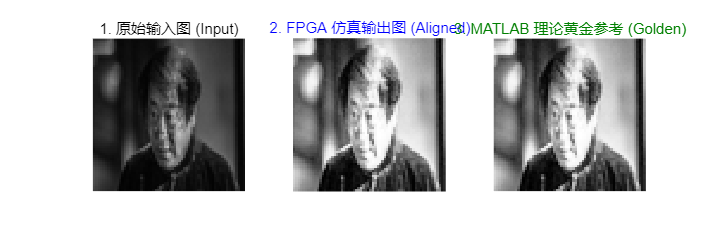


% 应用对齐后的像素并重组为二维图像
sim_aligned_1d = circshift(sim_raw_1d, best_shift);
img_sim = reshape(uint8(sim_aligned_1d), [WIDTH, HEIGHT])';

% -------------------------------------------------------------------------
% 5. 图像显示与逐像素误差评估
% -------------------------------------------------------------------------
diff_map  = abs(double(img_sim) - double(img_golden));
max_diff  = max(diff_map(:));
mean_diff = mean(diff_map(:));

figure('Name', 'FPGA 图像处理算法验证（已对齐）', 'Position', [100, 200, 1200, 400]);

subplot(1, 3, 1);
imshow(img_raw);
title('1. 原始输入图 (Input)', 'FontSize', 12);

subplot(1, 3, 2);
imshow(img_sim);
title('2. FPGA 仿真输出图 (Aligned)', 'FontSize', 12, 'Color', 'b');

subplot(1, 3, 3);
imshow(img_golden);
title('3. MATLAB 理论黄金参考 (Golden)', 'FontSize', 12, 'Color', [0 0.5 0]);

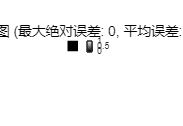


figure('Name', '误差热力图分析', 'Position', [200, 200, 600, 450]);
imshow(diff_map, []); colorbar;
title(sprintf('像素差值热力图 (最大绝对误差: %d, 平均误差: %.4f)', max_diff, mean_diff), 'FontSize', 11);


fprintf('\n============== 最终验证结果评估 ==============\n');


============== 最终验证结果评估 ==============


fprintf('最大绝对像素误差: %d (灰度级 0~255)\n', max_diff);

最大绝对像素误差: 0 (灰度级 0~255)


fprintf('平均像素误差: %.4f\n', mean_diff);

平均像素误差: 0.0000


if max_diff == 0
    fprintf('【完美】FPGA 输出与理论算法 100%%%% 完全一致（0 误差逐比特匹配）！\n');
elseif max_diff <= 1
    fprintf('【极高精度】最大误差仅为 1（属于定点数最末位舍入差异，完全正常）。\n');
elseif max_diff <= 3
    fprintf('【合格】算法正确，存在微小定点化误差。\n');
else
    fprintf('【注意】误差仍为 %d，请检查 Testbench 中是否至少输入了 2 帧完整图像。\n', max_diff);
end

【完美】FPGA 输出与理论算法 100%% 完全一致（0 误差逐比特匹配）！


fprintf('=============================================\n');